# **Project Title: Early Pest Detection using Image Processing**

## Image acquisition & pre-processing

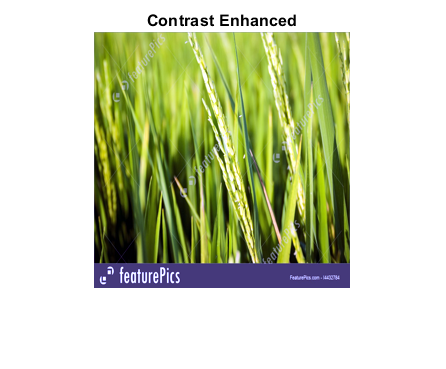

clc
close all 
clear all

[filename, pathname] = uigetfile({'*.*';'*.jpg';'*.png'}, 'Pick a Crop Image File');
I = imread([pathname,filename]);
I = imresize(I,[256,256]);

% Enhance Contrast
I = imadjust(I,stretchlim(I));
figure, imshow(I);
title('Contrast Enhanced');

## Detect Presence of Pest

Image Segmentation

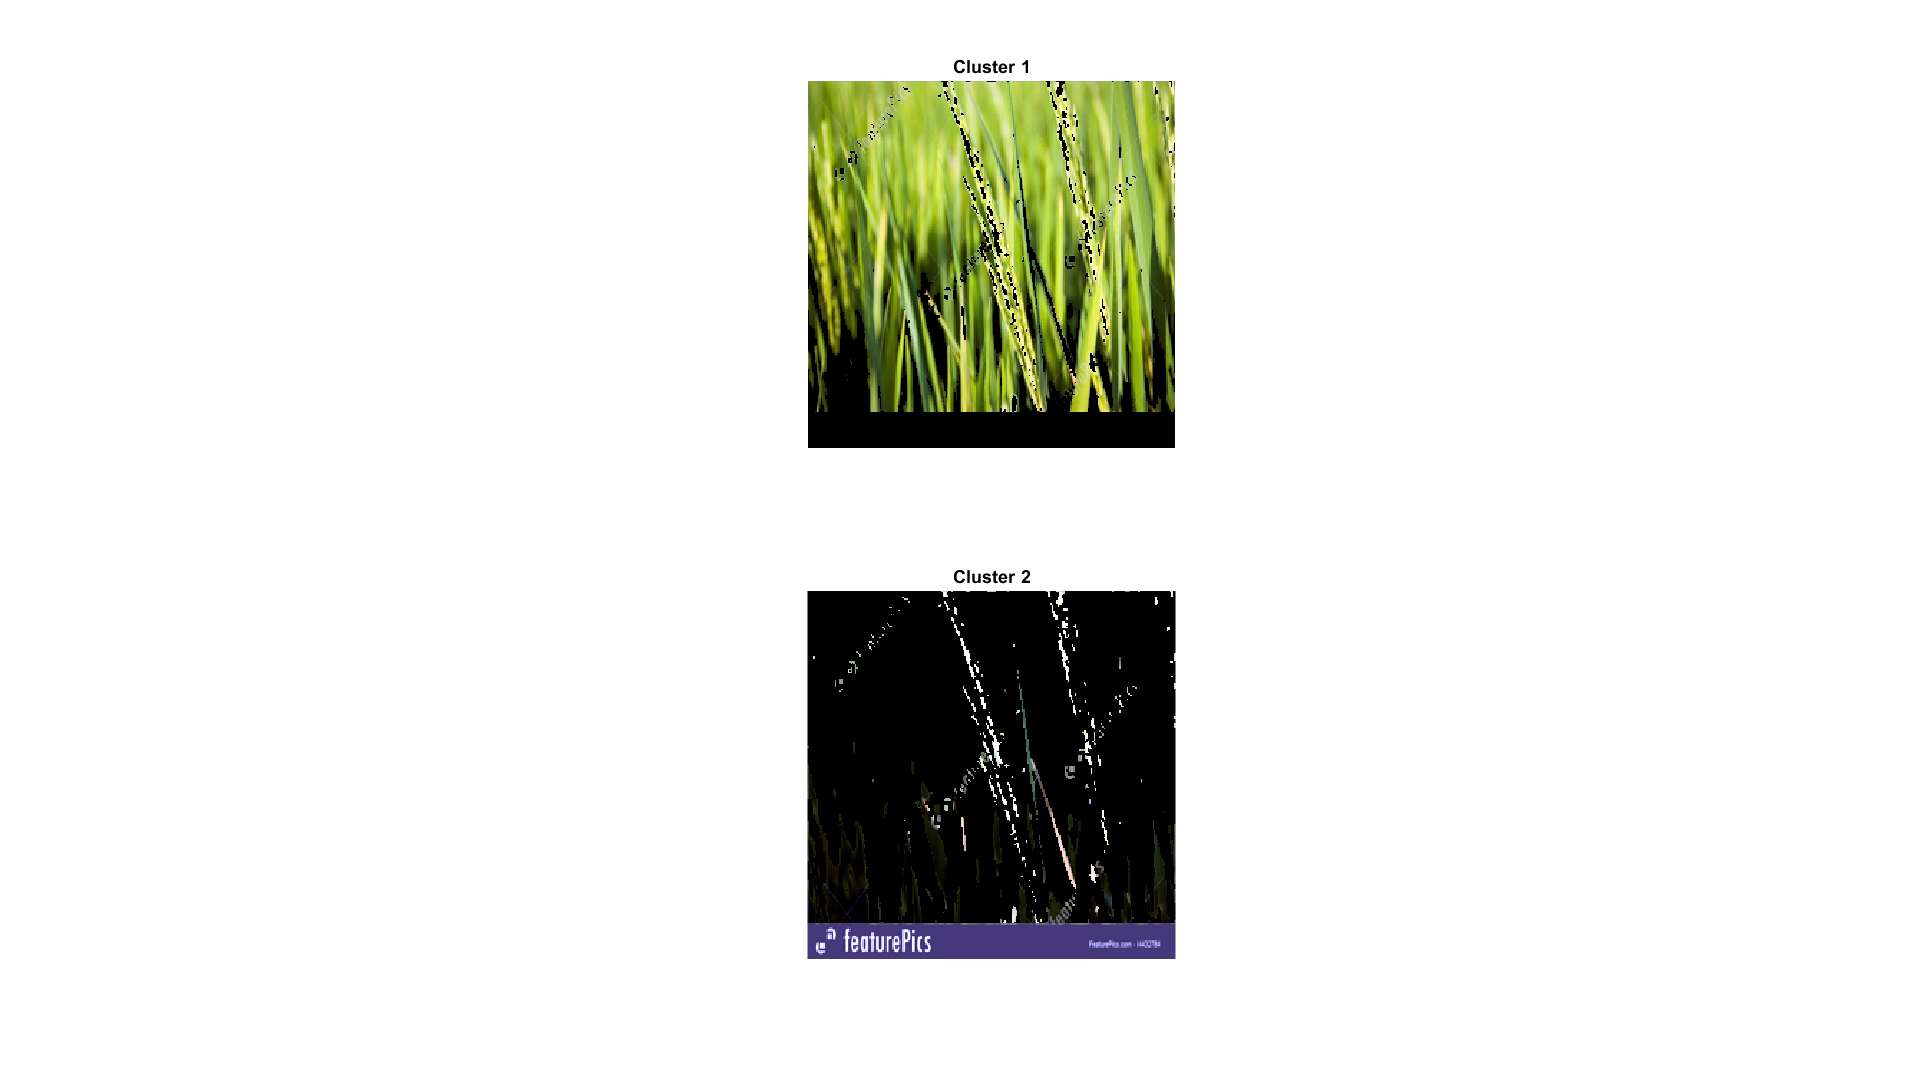

% Color Image Segmentation
% Use of K Means clustering for segmentation
% Convert Image from RGB Color Space to L*a*b* Color Space 
% The L*a*b* space consists of a luminosity layer 'L*', chromaticity-layer 'a*' and 'b*'.
% All of the color information is in the 'a*' and 'b*' layers.
cform = makecform('srgb2lab');
% Apply the colorform
lab_he = applycform(I,cform);

% Classify the colors in a*b* colorspace using K means clustering.
% Create 2 clusters.
% Measure the distance using Euclidean Distance Metric.
ab = double(lab_he(:,:,2:3));
nrows = size(ab,1);
ncols = size(ab,2);
ab = reshape(ab,nrows*ncols,2);
nColors = 2;
[cluster_idx, cluster_center] = kmeans(ab,nColors,'distance','sqEuclidean','Replicates',2);
% Label every pixel in tha image using results from K means
pixel_labels = reshape(cluster_idx,nrows,ncols);

% Create a blank cell array to store the results of clustering
segmented_images = cell(1,3);
% Create RGB label using pixel_labels
rgb_label = repmat(pixel_labels,[1,1,3]);

for k = 1:nColors
    colors = I;
    colors(rgb_label ~= k) = 0;
    segmented_images{k} = colors;
end

figure, 
subplot(2,1,1);imshow(segmented_images{1});title('Cluster 1'); 
subplot(2,1,2);imshow(segmented_images{2});title('Cluster 2');
set(gcf, 'Position', get(0,'Screensize'));

% Feature Extraction
x = inputdlg('Enter the cluster no. containing the ROI only:');

i = str2double(x);
seg_img = segmented_images{i};

% Convert to grayscale if image is RGB
if ndims(seg_img) == 3
   img = rgb2gray(seg_img);
end

cform = makecform('srgb2lab');
% Apply the colorform
lab_he = applycform(seg_img,cform);
img = rgb2gray(lab_he);
glcms = graycomatrix(img);

% Derive Statistics from GLCM
stats = graycoprops(glcms,'Contrast Correlation Energy Homogeneity');
Contrast = stats.Contrast;
Correlation = stats.Correlation;
Energy = stats.Energy;
Homogeneity = stats.Homogeneity;

Test_Feat = [];
feat_pest = [Contrast, Correlation, Energy, Homogeneity];
Test_Feat = [Test_Feat;feat_pest];

Image Classiffication - Testing

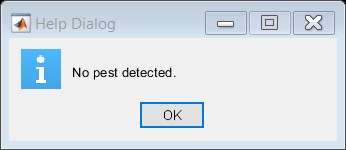

No pest detected.


%load trainging data
load('Train_Presence_Data.mat')

% Put the test features into variable 'test'
test = feat_pest;
result = multisvm(Train_Feat,Train_Label,test);

% Visualize Results
if result == 1
    helpdlg('Pest detected.');
    disp('Pest detected.');
    pause(3);
    Test_Phase
elseif result == 2
    helpdlg('No pest detected.');
    disp('No pest detected.');
end